# 图片沿特定轨迹运动

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

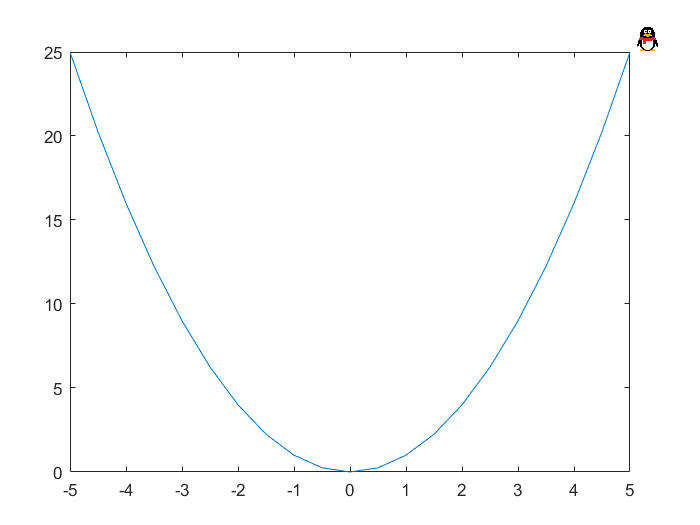

clear; clc;
% 生成轨迹
x = - 5 : 0.5 : 5;
y = x.^2;
minX = min(x);
maxX = max(x);
minY = min(y);
maxY = max(y);
% 在特定位置绘制轨迹图
h1 = axes('position', [0.1, 0.1, 0.8, 0.8]);
plot(x, y);
% 设置显示范围
xlim([minX, maxX]);
ylim([minY, maxY]);
% 图片尺寸
sizeQQ = 0.05;
posX = 0.1;
poxY = 0.85;
% 图像的位置
h2 = axes('position', [posX poxY sizeQQ sizeQQ]);
% 显示图片
imshow('qq.bmp');
for i = 1 : length(x)
    % 计算图片的位置
    posX = (x(i) - minX) / (maxX - minX) * 0.8 + 0.1;
    posY = (y(i) - minY) / (maxY - minY) * 0.8 + 0.1;
    % 删除之前的图片
    delete(h2);
    % 在新的位置显示
    h2 = axes('position', [posX posY sizeQQ sizeQQ]); 
    imshow('qq.bmp');
    % 暂停以显示动态过程
    pause(0.1);
end